# Lecture #8 Notes

# k-means clustering                                 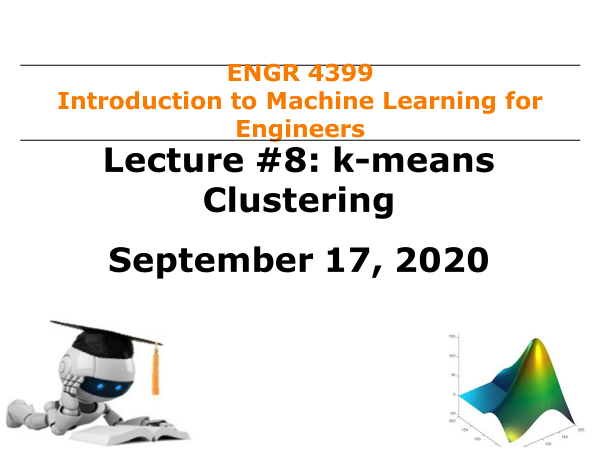

## Process to Develop Machine Learning Algorithms

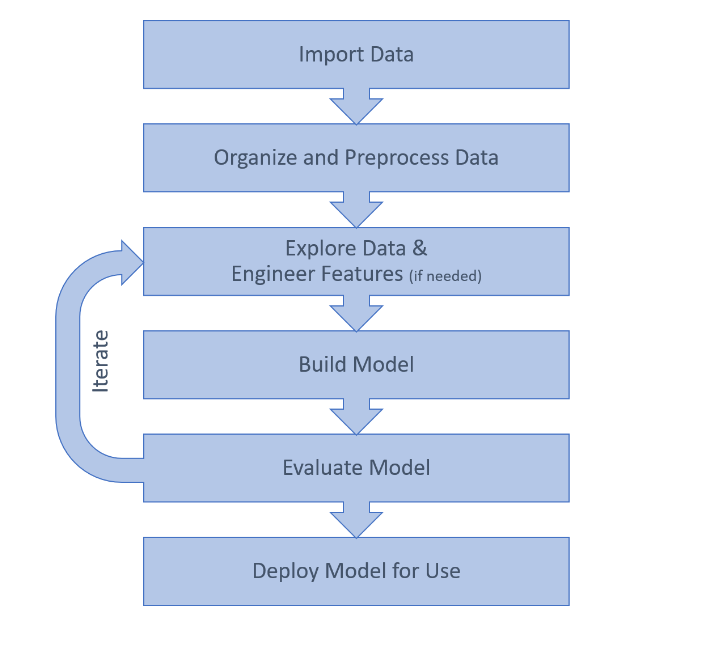

## 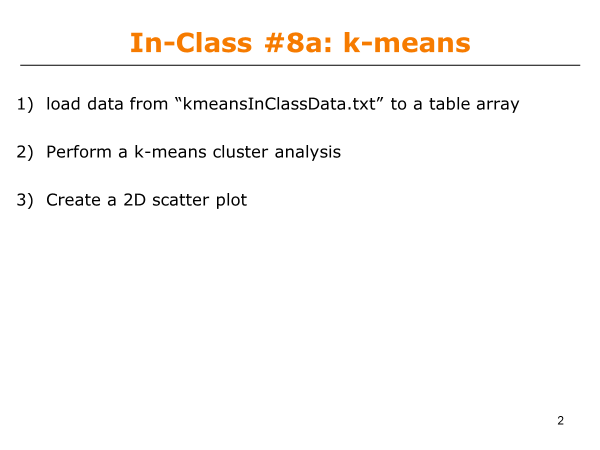

X = readtable('kmeansInClassData.txt')
X = table2array(X);
grp = kmeans(X,4);
[X,grp]
scatter(X(:,1),X(:,2),30,grp, 'filled')

## k-means

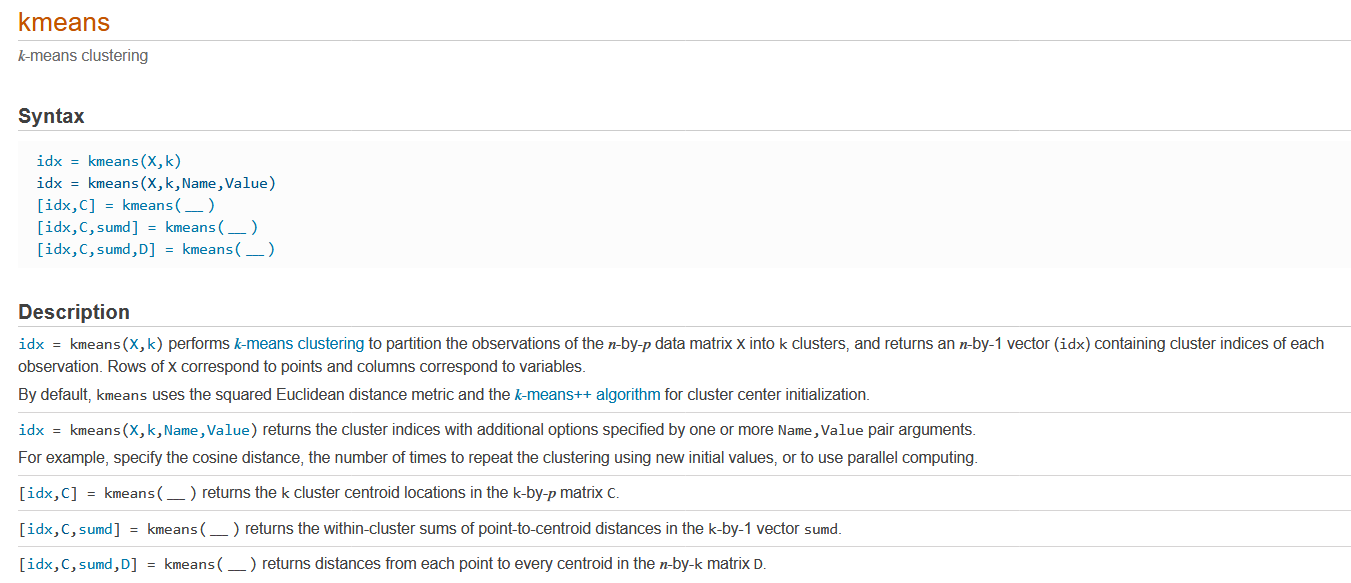

load kmeansdata.mat
whos

## TODO - TASK 1: Group X into four groups. Name the output grp

k = 4; %four clusters
grp = kmeans(X,k);
[grp,C] = kmeans(X,k,'Display','final','Replicates',2);
[grp,C,sumd] =  kmeans(X,k,'Distance','cityblock','Display','final','Replicates',2);
[grp,C,sumd,D] = kmeans(X,k,'Distance','cosine','Display','final','Replicates',2);

%% TODO - Task 2: You can visualize the results by viewing the data in a 
% scatter plot and assigning each group a different color. 
% Give the vector of groups as an additional fifth input argument 
% to the scatter function.
scatter(X(:,1),X(:,2),30,grp,'filled')
scatter3(X(:,1),X(:,2),X(:,2),30,grp,'filled')

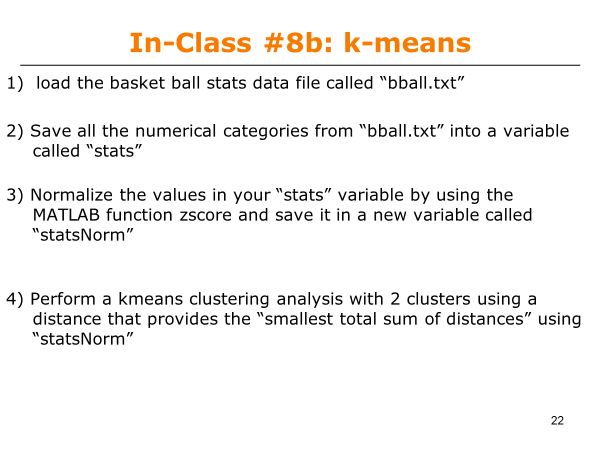

%% Import & intialize data
data = readtable('bball.txt');
stats = data{:,[ 5 6 11:end ]};
labels = data.Properties.VariableNames([ 5 6 11:end ]);
statsNorm = zscore(stats);

%% TODO: Group data using k-means clustering
[grp,C,sumd] = kmeans(statsNorm,2,'Distance','cityblock','Replicates',5,'Display','final');
[grp,C,sumd] = kmeans(statsNorm,2,'Distance','sqeuclidean','Replicates',5,'Display','final');
[grp,C,sumd] = kmeans(statsNorm,2,'Distance','cosine','Replicates',5,'Display','final');
